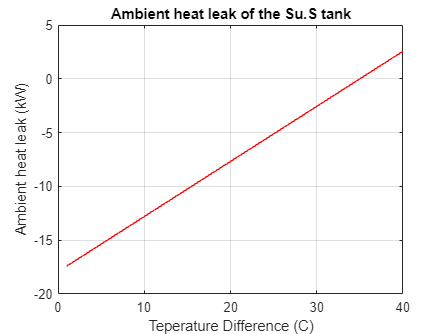

% Known geometrical parameters
h_vessel = 8;         % m
d_vessel = 2;         % m
v_vessel = 12;        % m3
wall_t_vessel= 0.1;   % m

% Known thermodynamic parameters
T_ambient(1) = -20;    % C
T_vessel = 15;        % C
P_vessel = 50;        % bar
k_vessel = 16.3;      % W/mK (Thermal Conductivity)

% Calculations
A = pi * ((d_vessel^2)/4);              % m2
U_vessel = 1/(wall_t_vessel/k_vessel);  % W/m2K 

% Ambient heat leak

for i = 1:40;
    T_ambient(i+1) = T_ambient(i) + 1;     % C
    DT(i) = T_ambient(i+1) - T_vessel;     % C
    Q(i) = (U_vessel * A * DT(i))/1e3;     % kW
end

% Plot ambient heat leak
plot(Q,'LineWidth',1,'Color','r');
xlabel('Teperature Difference (C)');
ylabel('Ambient heat leak (kW)');
title('Ambient heat leak of the Su.S tank');
grid on;